solve(symbolic eqn, var)   => Symbolisch oplossen      

fzero(matlab eqn, x0) => Soort bisectie            

**4.1**

clear ; close all; clc

syms x
f = exp(2*x) - 5*exp(x) + 6

$$f = {\mathrm{e}}^{2\,x}-5\,{\mathrm{e}}^{x}+6$$


fplot(f, "Color", "b")
solve(f)

$$ans = \left(\begin{array}{c} \log\left(2\right)\\ \log\left(3\right) \end{array}\right)$$

hold on
fplot(diff(f), "Color","r")

% ==
fplot(0, "Color", [.7 .7 .7])
axis([-2 2 -4 8])
legend()
% ==

**4.2**

roots(1:4)

ans =   -1.6506 + 0.0000i
  -0.1747 + 1.5469i
  -0.1747 - 1.5469i


f = poly2sym(1:4)

$$f = x^{3}+2\,x^{2}+3\,x+4$$

fzero(matlabFunction(f),-1)

ans = -1.6506

fsolve(matlabFunction(f),-1+1i)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = -1.6506 - 0.0000i

**4.3**

syms a b c t x

roots([a b c])

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$


f = x^2 + cos(t)

$$f = x^{2}+\cos\left(t\right)$$


solve(f,x)

$$ans = \left(\begin{array}{c} \sqrt{-\cos\left(t\right)}\\ -\sqrt{-\cos\left(t\right)} \end{array}\right)$$

solve(f,t)

$$ans = \left(\begin{array}{c} \pi +\mathrm{acos}\left(x^{2}\right)\\ \pi -\mathrm{acos}\left(x^{2}\right) \end{array}\right)$$


f = sin(x) - cos(x)

$$f = \sin\left(x\right)-\cos\left(x\right)$$

solve(f,x)

$$ans = \frac{\pi }{4}$$


fsolve(matlabFunction(exp(x) - tan(x)), 1, optimset('Display','off'))

ans = 1.3063

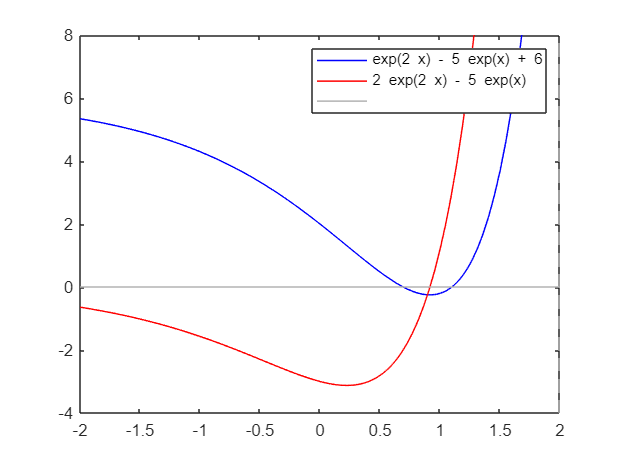


hold off

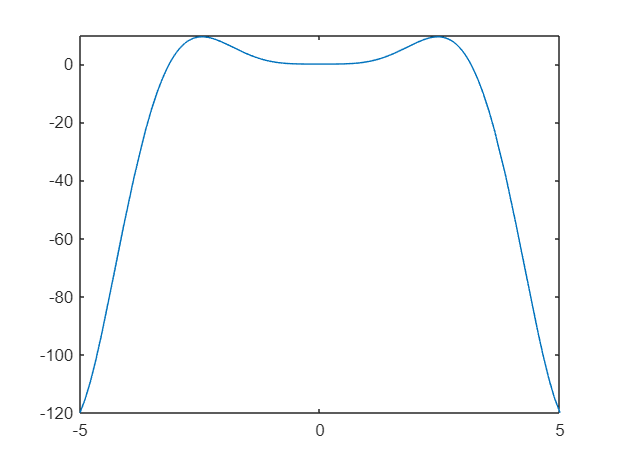

fplot(x^3*sin(x)) % -pi 0 pi

fsolve(@(x) x^3*sin(x), 5, optimset('Display','off'))

ans = 3.1416

**4.4**

syms t z
h = -0.12*t^4+12*t^3-380*t^2+4100*t+220

$$h = -\frac{3\,t^{4}}{25}+12\,t^{3}-380\,t^{2}+4100\,t+220$$


fplot(h)
hold on
grid on
fplot(diff(h))
fplot(diff(h,2))
legend("Derivative "+num2str([0 1 2]'))

mh = matlabFunction(h);
x = fsolve(matlabFunction(diff(h)),1, optimset('Display','off'));
fprintf("maximum at h=%f at t = %f\n",mh(x),x)

maximum at h=14363.755314 at t = 8.290766


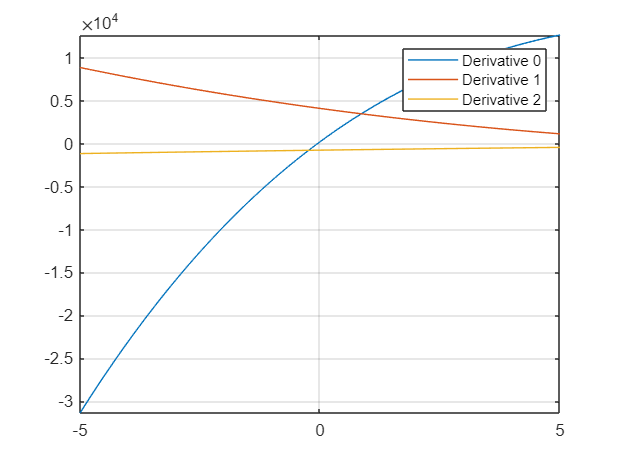

hold off

**4.5**

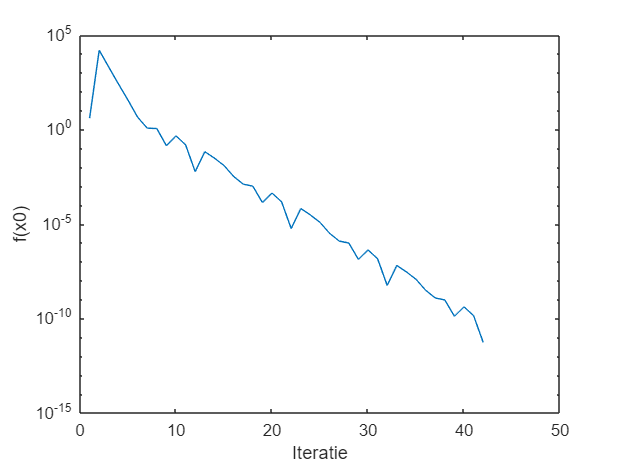

toleration: 1e-10
Iterations: 42
Theory?: 39.8631


ans = 1.0000

f = @(E) bisection(@(x) x^3 + 3*x - 4, -50, 50, E, 100, true);
syms i

f(1e-10)

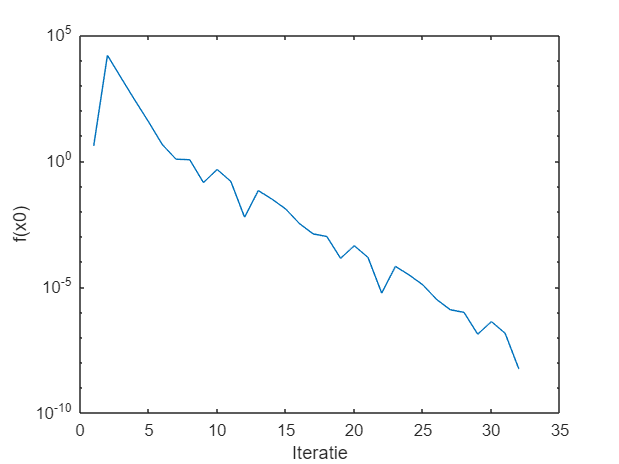

toleration: 1e-07
Iterations: 32
Theory?: 29.8974


ans = 1.0000

f(1e-7)

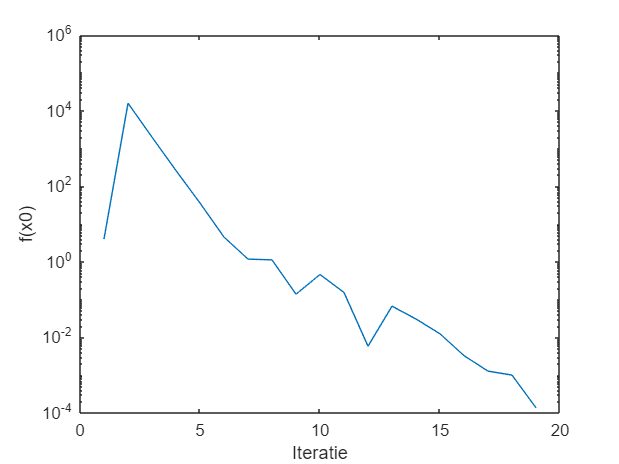

toleration: 0.001
Iterations: 19
Theory?: 16.6096


ans = 1.0000

f(1e-3)

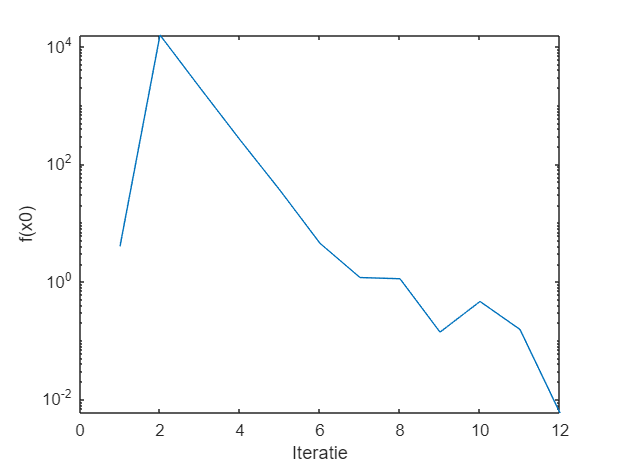

toleration: 0.1
Iterations: 12
Theory?: 9.9658


ans = 1.0010

f(1e-1)

disp("=======")

**4.6**

bisection(@(x) x^3 - 3*x + 2, -1, 2, 1e-3, 100,false)

a and b do not pass 0!
Couldn't found x


ans = 2

Geen tekenwissel

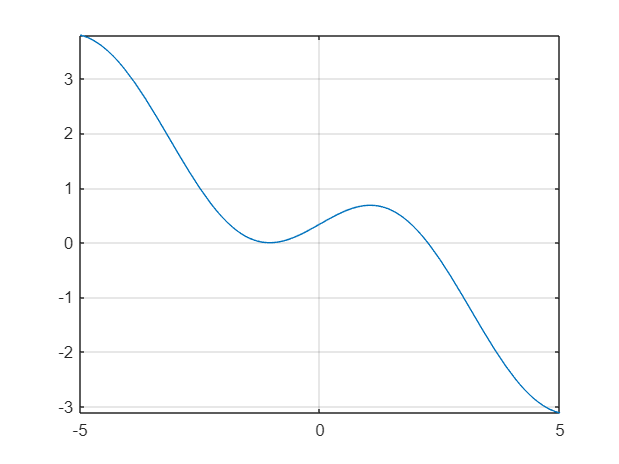

f = @(x) sin(x) - x/2 - pi/6 + sqrt(3)/2;
fplot(f)
grid on

bisection(f, 1, 3, 1e-3, 100,false)

toleration: 0.001
Iterations: 9
Theory?: 16.6096


ans = 2.2461